2. Com base na função fft(.) do Matlab, desenvolva uma função no MATLAB, denominada Espetro, que retorna e apresenta o espetro (amplitude apenas) de um sinal (passado através do seu vetor de amostras, 𝐱) amostrado com período de amostragem 𝑇𝑎. O gráfico do espetro deve apresentar no eixo das abcissas a frequência em Hz, desde −𝑓𝑎/2 a +𝑓𝑎/2, onde 𝑓0=1/𝑇0.

function [𝐗 ,f]=𝐸𝑠𝑝𝑒𝑡𝑟𝑜 ( 𝐱 ,𝑇𝑎)

𝐗 – vetor da mesma dimensão de 𝐱, com os coeficientes da DFT de 𝑥(𝑡).

𝑓 – vetor da mesma dimensão de 𝐱, com as frequências (em Hz) de cada componente de 𝐗.

clc;clear;close all;

f0 = 10; fa = 20 * f0; Ta = 1/fa; T = 1 / f0;

n_periodos = 100;

N = n_periodos*T - Ta;

t= (0:Ta:T*n_periodos);
x = 10+14*cos(20*pi*t - pi/3) + 8*cos(40*pi*t + pi/3); 

[X, f] = Espectro(x, Ta);


3. Teste a função desenvolvida no ponto anterior, representando o espectro dos seguintes sinais:

a) 𝑥(𝑡)=sin (2𝜋𝑡), registado durante 2 e 100 períodos.

clc;clear;close all;

f0 = 10; fa = 20 * f0; Ta = 1/fa; T = 1 / f0;

n_periodos = 100;

N = n_periodos*T - Ta;

t= (2:Ta:T*n_periodos);

x = sin(2*pi*t); 

[X, f] = Espectro(x, Ta);

b) 𝑦(𝑡)=sin(10𝜋𝑡)+cos(12𝜋𝑡)+cos (14𝜋𝑡−𝜋/4), registado durante 50 seg.

clc;clear;close all;

f0 = 10; fa = 20 * f0; Ta = 1/fa; T = 1 / f0;

n_periodos = 50;

t= (0:Ta:n_periodos-Ta);

x = sin(10*pi*t)+cos(12*pi*t)+cos(14*pi*t-pi/4);

[X, f] = Espectro(x, Ta);

c) 𝑦(𝑡)=10+14cos(20𝜋𝑡−𝜋/3)+8cos (40𝜋𝑡+𝜋/2), registado durante 100 períodos.

clc;clear;close all;

f0 = 10; fa = 20 * f0; Ta = 1/fa; T = 1 / f0;

n_periodos = 100;

N = n_periodos*T - Ta;

t= (0:Ta:T*n_periodos);
x = 10+14*cos(20*pi*t - pi/3) + 8*cos(40*pi*t + pi/3); 

[X, f] = Espectro(x, Ta);

d) 𝑧(𝑡) – onda quadrada entre 0 e 1, de frequência 1 Hz, registada durante 5 seg.

clc;clear;close all;

f0 = 1; fa = 20 * f0; Ta = 1/fa; T = 1 / f0;

n_periodos = 50; 
t = (0:Ta:n_periodos-Ta);

z = (square(2*pi*t*f0)+1)/2; 

[X, f] = Espectro(z, Ta);

e) 𝑞(𝑡) - onda triangular entre -1 e 1, de frequência 1 Hz, registada durante 5 seg.

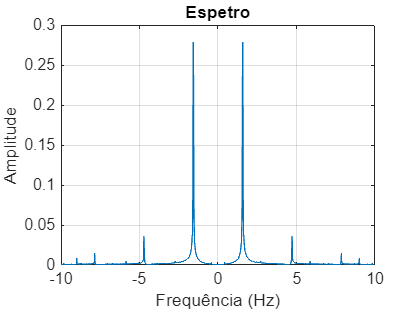

clc;clear;close all;

f0 = 1; fa = 20 * f0; Ta = 1/fa; T = 1 / f0;

n_periodos = 50; 
t = (0:Ta:n_periodos-Ta);

q = sawtooth(2*pi*t*+pi/2, 1/2); 

[X, f] = Espectro(q, Ta);

4. Desenvolva, agora, e com base na função ifft(.) do Matlab, a função Reconstroi que efetua a operação inversa da função desenvolvida na pergunta 2 (i.e., recebendo o vetor 𝐗 da representação em Fourier, reconstrói a sequência de amostras do sinal no domínio do tempo, 𝐱, visualizando, depois, o sinal reconstruído). Teste a função com os dados obtidos nas perguntas anteriores.

clc;clear;close all;

f0 = 10; fa = 20 * f0; Ta = 1/fa; T = 1 / f0;

n_periodos = 100;

N = n_periodos*T - Ta;

t= (0:Ta:T*n_periodos);
x = 10+14*cos(20*pi*t - pi/3) + 8*cos(40*pi*t + pi/3); 

[X, f] = Reconstroi(x, t);